# Lab - 03

## Question 1

Matrices are generated of size n=4, with a = 2 and b = 5.

format long e;
n = 4; a = 2; b = 5;
r = a + (b-a).*rand(n,1);
D = diag(r);
B = randn(n);
[Q,R] = qr(B);
A = Q'*D*Q;


disp('G obtained by mychol');

G obtained by mychol


G = mychol(A);
G

G =      2.161826732684207e+00     7.902881370798288e-02    -2.288073307626368e-01     3.362697557402073e-02
                         0     1.928783958965199e+00     5.937078830572159e-02    -1.518759863833876e-01
                         0                         0     1.570640603372116e+00     7.551596626988114e-02
                         0                         0                         0     2.041814818139079e+00



disp('Actual G (matlab)');

Actual G (matlab)


G_hat = chol(A);
G_hat

G_hat =      2.161826732684207e+00     7.902881370798288e-02    -2.288073307626368e-01     3.362697557402073e-02
                         0     1.928783958965199e+00     5.937078830572159e-02    -1.518759863833877e-01
                         0                         0     1.570640603372116e+00     7.551596626988116e-02
                         0                         0                         0     2.041814818139079e+00



disp('Difference in norms');

Difference in norms


diff = norm(G - G_hat)

diff =      4.461231280182576e-16



disp('Difference in A - G''*G');

Difference in A - G'*G


ans = norm(A - G.'*G)

ans =      5.323563250704054e-16


We see that norm(G - G_hat) is very small for all examples and so is A - G'G, which means mychol is working well.

format long e;
n = 5; a = 1; b = 8;
r = a + (b-a).*rand(n,1);
D = diag(r);
B = randn(n);
[Q,R] = qr(B);
A = Q'*D*Q;


disp('G obtained by mychol');

G obtained by mychol


G = mychol(A);
G

G =      2.302451729063065e+00    -4.599383129724431e-01     1.979306612076605e-01    -3.848456134941285e-01    -2.267044751493858e-01
                         0     2.088681425181270e+00     4.052091709884713e-01     6.663775588654283e-01    -7.333465142856519e-01
                         0                         0     2.215330124284657e+00    -7.123782967844489e-01    -3.513110838253868e-01
                         0                         0                         0     1.793047072759897e+00    -2.726841764121444e-01
                         0                         0                         0                         0     1.877192700816008e+00



disp('Actual G (matlab)');

Actual G (matlab)


G_hat = chol(A);
G_hat

G_hat =      2.302451729063065e+00    -4.599383129724431e-01     1.979306612076605e-01    -3.848456134941285e-01    -2.267044751493858e-01
                         0     2.088681425181270e+00     4.052091709884713e-01     6.663775588654283e-01    -7.333465142856519e-01
                         0                         0     2.215330124284657e+00    -7.123782967844488e-01    -3.513110838253868e-01
                         0                         0                         0     1.793047072759897e+00    -2.726841764121444e-01
                         0                         0                         0                         0     1.877192700816008e+00



disp('Difference in norms');

Difference in norms


diff = norm(G - G_hat)

diff =      1.270231481815119e-16



disp('Difference in A - G''*G');

Difference in A - G'*G


ans = norm(A - G.'*G)

ans =      9.458142285496507e-16


format long e;
n = 6; a = 2; b = 7;
r = a + (b-a).*rand(n,1);
D = diag(r);
B = randn(n);
[Q,R] = qr(B);
A = Q'*D*Q;


disp('G obtained by mychol');

G obtained by mychol


G = mychol(A);
G

G =      1.617010679732658e+00    -1.453181336578536e-01    -1.432599197938910e-01    -1.804464541371695e-01     4.202888961254010e-02     9.514449460626290e-03
                         0     1.792407215272538e+00     7.989947559599010e-02     7.521263493134558e-02    -2.315699284189046e-01    -3.338637941505579e-03
                         0                         0     1.754947919051576e+00    -5.825863862415191e-02    -3.189911730078940e-02    -6.273302663732953e-02
                         0                         0                         0     1.762759557728264e+00    -7.322329765998040e-02    -5.676803131475428e-02
                         0                         0                         0                         0     1.865128369155069e+00     6.462281691937843e-02
                         0                         0                         0                         0                         0     1.633460582848456e+00



disp('Actual G (matlab)');

Actual G (matlab)


G_hat = chol(A);
G_hat

G_hat =      1.617010679732658e+00    -1.453181336578536e-01    -1.432599197938910e-01    -1.804464541371696e-01     4.202888961254010e-02     9.514449460626292e-03
                         0     1.792407215272538e+00     7.989947559599012e-02     7.521263493134558e-02    -2.315699284189046e-01    -3.338637941505580e-03
                         0                         0     1.754947919051576e+00    -5.825863862415191e-02    -3.189911730078940e-02    -6.273302663732953e-02
                         0                         0                         0     1.762759557728264e+00    -7.322329765998037e-02    -5.676803131475427e-02
                         0                         0                         0                         0     1.865128369155069e+00     6.462281691937842e-02
                         0                         0                         0                         0                         0     1.633460582848456e+00



disp('Difference in norms');

Difference in norms


diff = norm(G - G_hat)

diff =      2.258722128719805e-16



disp('Difference in A - G''*G');

Difference in A - G'*G


ans = norm(A - G.'*G)

ans =      9.510158275315678e-16


Norms are small for above and below examples as well.

## Question 2

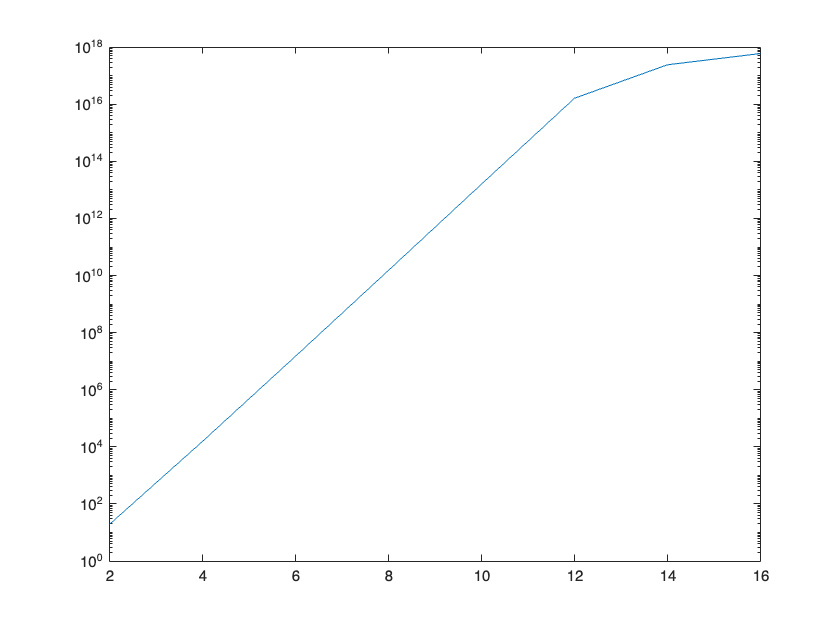

% 2-norm
C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H)];
end
semilogy(N,C)

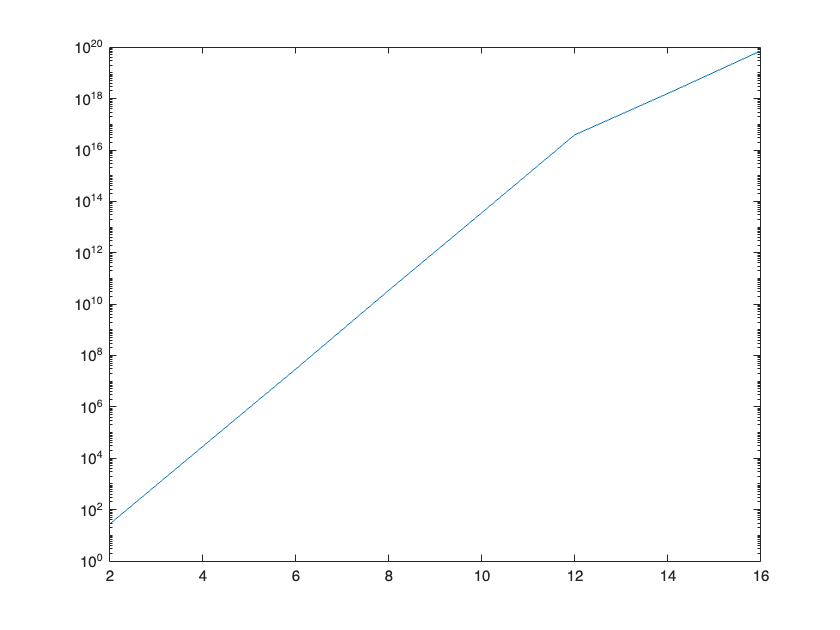


% 1-norm
C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H,1)];
end
semilogy(N,C)


% inf-norm
C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H,inf)];
end
semilogy(N,C)

From the graphs we observe that cond(H) vs n is linear on the semi-log y plot, which is plot() function with scale on y-axis as logarithmic base 10. We can say that the cond(H) depends on n exponentially and is increasing exponentially as the power or 10 with increasing n. Beyond 10^15, linearity is sort of lost and matrix becomes ill-conditioned and is nearly singular. 

## Question 3

format long e;
N = 8:2:12;
for n = N
    H = hilb(n);
    HI = invhilb(n);
    x = rand(n,1);
    b = H*x;
    % Using \
    x1 = H\ b;
    
    % Using inverse
    x2 = HI*b;
    
    % Using geppsolve
    x3 = geppsolve(H,b);
    

    fprintf('X for n = %d',n);
    arr = [x x1 x2 x3]
    
    disp('condition number and norms');
    arr = [cond(H) norm(x-x1)/norm(x) norm(x-x2)/norm(x) norm(x-x3)/norm(x)]
end

X for n = 8

arr =      3.684845964903365e-01     3.684845964977763e-01     3.684845964780834e-01     3.684845964977763e-01
     6.256185607296904e-01     6.256185603405068e-01     6.256185616366565e-01     6.256185603405068e-01
     7.802274351513768e-01     7.802274401903563e-01     7.802274320274591e-01     7.802274401903563e-01
     8.112576886578526e-02     8.112574164364657e-02     8.112581074237823e-02     8.112574164364657e-02
     9.293859709687300e-01     9.293860443523918e-01     9.293859899044037e-01     9.293860443523918e-01
     7.757126786084023e-01     7.757125744964457e-01     7.757127881050110e-01     7.757125744964457e-01
     4.867916324031724e-01     4.867917067344532e-01     4.867915511131287e-01     4.867917067344532e-01
     4.358585885809191e-01     4.358585675371830e-01     4.358586072921753e-01     4.358585675371830e-01


condition number and norms


arr =      1.525757605283408e+10     8.697640910948613e-08     8.332243390183830e-08     8.697640910948613e-08


X for n = 10

arr =      4.467837494298063e-01     4.467837492613074e-01     4.467837490956299e-01     4.467837492613074e-01
     3.063494720165574e-01     3.063494884655824e-01     3.063495196402073e-01     3.063494884655824e-01
     5.085086553811270e-01     5.085082743975847e-01     5.085080862045288e-01     5.085082743975847e-01
     5.107715641721097e-01     5.107752461275197e-01     5.107803344726562e-01     5.107752461275197e-01
     8.176277083222621e-01     8.176093079989650e-01     8.176345825195312e-01     8.176093079989650e-01
     7.948314168834530e-01     7.948838909898563e-01     7.949371337890625e-01     7.948838909898563e-01
     6.443181301936917e-01     6.442294439540545e-01     6.441040039062500e-01     6.442294439540545e-01
     3.786093826602684e-01     3.786972102834078e-01     3.787231445312500e-01     3.786972102834078e-01
     8.115804582824772e-01     8.115333935876647e-01     8.113861083984375e-01     8.115333935876647e-01
     5.328255887994549e-01     5.328361213029985e

condition number and norms


arr =      1.602489743907792e+13     7.624494333263343e-05     1.729435799898920e-04     7.624494333263343e-05


X for n = 12

arr =      3.507271035768833e-01     3.507271199225810e-01     3.507271297276020e-01     3.507271199225810e-01
     9.390015619998868e-01     9.389995625574534e-01     9.390009641647339e-01     9.389995625574534e-01
     8.759428114929838e-01     8.760038106959597e-01     8.759193420410156e-01     8.760038106959597e-01
     5.501563428984222e-01     5.493467914602671e-01     5.498046875000000e-01     5.493467914602671e-01
     6.224750860012275e-01     6.282749702271336e-01     6.303710937500000e-01     6.282749702271336e-01
     5.870447045314168e-01     5.620726635821005e-01     5.625000000000000e-01     5.620726635821005e-01
     2.077422927330285e-01     2.760781458238742e-01     2.421875000000000e-01     2.760781458238742e-01
     3.012463302794907e-01     1.795294203914261e-01     7.812500000000000e-02     1.795294203914261e-01
     4.709233485175907e-01     6.115620034690952e-01     5.468750000000000e-01     6.115620034690952e-01
     2.304881602115585e-01     1.288343081052113e

condition number and norms


arr =      1.636071866556670e+16     1.145602609094880e-01     1.298202417640649e-01     1.145602609094880e-01


By computing x1, x2, and x3 for n = 8, 10, and 12 we see a significant loss of accuracy. Specifically, 10, 13 and all 16 digits were lost for n = 8, n = 10 and n = 12 respectively as indicated by the condition numbers.

The computed values of x1, x2, and x3 for each n exhibit similar levels of error, as indicated by their comparable order of magnitude and consistent mantissa variations.

This observation of loss of accuracy goes along with the theoretical predictions of the Rule-of-Thumb. Specifically, the relative error, expressed as ||x – x’||/||x||, is consistently less than or equal to 0.5 * 10^(-p). This indicates that the computed values (x’) agree with the true values (x) to at least p significant digits for all entries.

## Question 4

n=10;
H=hilb(n);
x = randn(n,1);
b = H*x;

x1= H \ b;
r = H*x1-b;

disp([norm(r)/norm(b) norm(x-x1)/norm(x)])

     4.171146269450138e-16     1.197083543731111e-04



norm(r)/norm(b)

ans =      4.171146269450138e-16


norm(x-x1)/norm(x)

ans =      1.197083543731111e-04


The magnitude of ||r||/||b|| does not necessarily correlate with the magnitude of ||x – x’||/||x||. In this specific instance, ||x – x’||/||x|| is significantly larger, approximately 10^(-5) compared to 10^(-17) for ||r||/||b||. This discrepancy highlights that a small ||r||/||b|| alone is insufficient to determine the proximity of x to x’.

## Question 5

rng('default');

N = [32, 64];
cond_nums = [];
gepp_errors = [];
gepp_ratios = [];
qr_errors = [];
qr_ratios = [];

for n = N
    x = rand(n, 1);
    
    W = Wilkinson(n);
    b = W * x;

    % using geppsolve
    x1 = geppsolve(W, b);
    

    cond_nums = [cond_nums; cond(W, inf)];
    gepp_errors = [gepp_errors; norm(x - x1, inf) / norm(x, inf)];
    gepp_ratios = [gepp_ratios; norm(W * x1 - b, inf) / norm(b, inf)];


    [Q, R] = qr(W);
    x_qr = colbackward(R, Q' * b);
    qr_errors = [qr_errors; norm(x - x_qr, inf) / norm(x, inf)];
    qr_ratios = [qr_ratios; norm(W * x_qr - b, inf) / norm(b, inf)];
end

T = table(N', cond_nums, gepp_errors, qr_errors, gepp_ratios, qr_ratios, ...
    'VariableNames', {'n', 'Condition_Number', 'GEPP_Error', 'QR_Error', 'GEPP_Ratio', 'QR_Ratio'});

disp(T);

             n                Condition_Number           GEPP_Error               QR_Error               GEPP_Ratio               QR_Ratio      
    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________

    3.20000000000000e+01    3.20000000000000e+01    1.55614424824546e-09    3.57456496395963e-15    2.34242378177623e-10    4.76719071915660e-16
    6.40000000000000e+01    6.40000000000018e+01    3.57613958266690e+00    1.16257479908855e-14    2.32835225097688e-01    7.53847468373482e-16



a) The QR decomposition method showed significantly lower numerical errors compared to the Gaussian elimination with partial pivoting (GEPP) method. QR decomposition errors were on the order of 10^(-14) to 10^(-15), while GEPP errors were nearly 10^(-9) and 10^(0).

b) The Rule-of-Thumb accurately predicted the error behavior for the QR decomposition method. With t = 1 for both n = 32 and n = 64, the predicted forward error of s - t = 15 closely matched the actual computed errors. However, the accuracy of GEPP is overestimated by the Rule-of-Thumb. For n = 32, the observed error was on the order of 10^(-9), significantly larger than the predicted 10^(-16).

c) The QR decomposition method consistently produced lower infinity norm ratios for both n = 32 and n = 64, on the order of 10^(-16).

d) The QR decomposition method demonstrated backward stability, as supported by the computed data and Rule-of-Thumb analysis. In contrast, GEPP was found to be numerically unstable, indicating a lack of backward stability.

# **Functions **

function G = mychol(A)
    [n,~] = size(A);
    if A(1,1) <= 0
        error('Oops! Negative diagonol entry encountered');
    end
    
    G = zeros(n,n);
    g11 = sqrt(A(1,1));
    G(1,1) = g11;
    
    if n==1
        return;
    end
    b = A(1,2:n).';
    A_hat = A(2:n,2:n);
    
    g = b/g11;
    
    G(1,2:n) = g.';
    G(2:n,2:n) = mychol(A_hat - g*g.');
    return;
end


function x = colbackward(U, b)
    [n, ~] = size(U);
    x = zeros(n, 1);
    for i = n:-1:1
        if U(i,i) ~= 0
            x(i) = b(i) / U(i,i);
        else
            error('Matrix is singular');
        end
        b(1:i-1) = b(1:i-1) - U(1:i-1,i) * x(i);
    end
end


function x = rowforward(L, b)
    [n, ~] = size(L);
    x = zeros(n, 1);
    for k = 1:n
        for j = 1:k-1
            b(k) = b(k) - L(k, j) * x(j);
        end
        if L(k,k) ~= 0
            x(k) = b(k) / L(k,k);
        else
            error('Matrix is singular');
        end
    end
end

function [L, U, p] = gepp(A)    
    [n, ~] = size(A);
    p = (1: n);
    for k = 1:n-1
        [~, ind] = max(abs(A(k: end, k)));
        ind = ind+k-1;
        
        if ind ~= k
            A([ind, k],:) = A([k, ind],:);
            p([ind, k]) = p([k, ind]);
        end
        
        if A(k,k) ~= 0
            A(k+1:n,k) = A(k+1:n,k) / A(k,k);
        end
        
        A(k+1:n, k+1:n) = A(k+1:n,k+1:n) - A(k+1:n,k)*A(k,k+1:n);
    end
    
    L = eye(n) + tril(A, -1);
    U = triu(A);
end

function [x] = geppsolve(A, b)
    [n, ~] = size(A);
    [L, U, p] = gepp(A);
    y = rowforward(L, b(p, :));
    x = colbackward(U, y);
end


function W = Wilkinson(n)
    W = (tril(ones(n)) .* -1) + (eye(n) .* 2);
    W(:, end) = 1;
end
